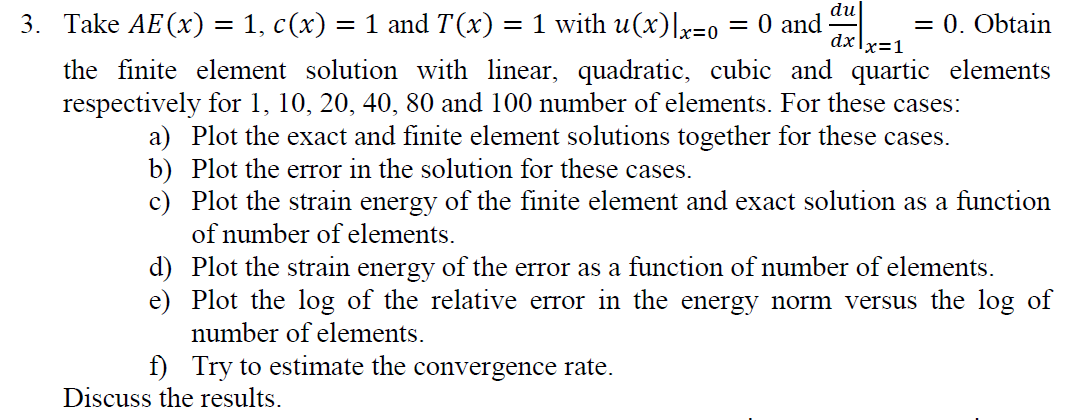

clc;
clear;
syms x

AE  = 1;
% Domain of X
x0 = 0;
xL = 1;
L = xL; % Length

a = AE;
% In spring case for a =1 only it is working, for plotting exact solution
b = 0;
c =0;
%f = 0;
%f = 0;

f =-sin(pi*x);

u_exact_equation = 0.1013*sin(3.142*x) + 0.03183

$$u\_exact\_equation = \frac{1013\,\sin\left(\frac{1571\,x}{500}\right)}{10000}+\frac{3183}{100000}$$


%u0 = 0; % Dirichlet value u at x0

Q0 = 1/pi% Neumann value (du/dx) at x0

Q0 = 0.3183


%K0 = % The spring constant K at x0 
%Del0 = % The spring displacement Del at x0


%uL = % The Dirichlet value u at xL

%P1 = 0; % The Neumann value (du/dx) at xL

K1 = 10% The spring constant K at xL 

K1 = 10

Del1 = 0% The spring displacement Del at xL

Del1 = 0

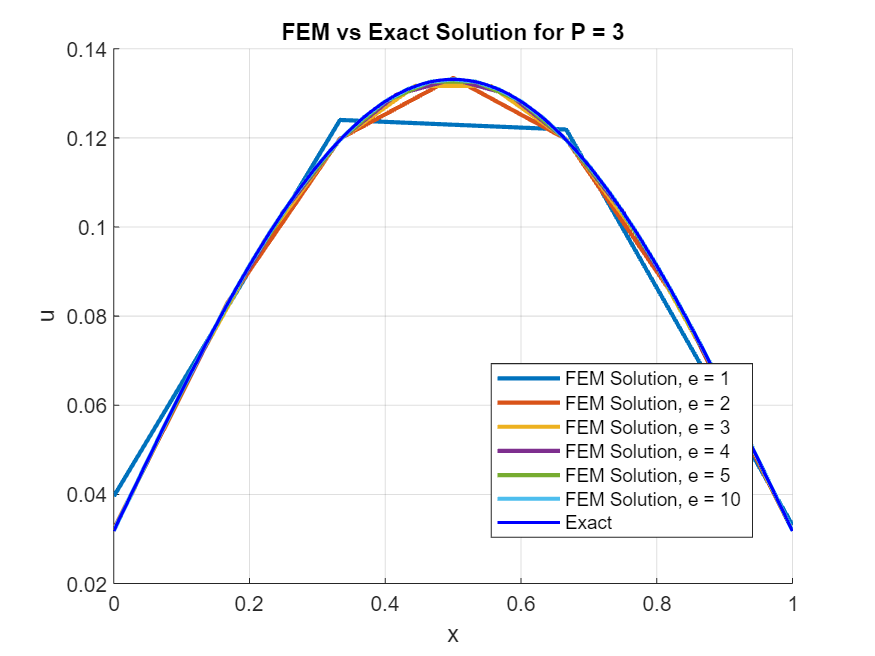



%elements = [1, 2, 5, 10, 50, 100];
elements = [1, 2,3,4,5,10];
P_values = [3];

% Initialize the matrices to store the h values and the FEM strain energies
h_values = zeros(length(elements), length(P_values));
% Initialize cell arrays to store u_nodes and X_nodes for each combination of P and elements
u_nodes_store = cell(length(elements), length(P_values));
X_nodes_store = cell(length(elements), length(P_values));

for p_idx = 1:length(P_values)
    P = P_values(p_idx);
    for i = 1:length(elements)
    
        e = elements(i); % Current number of elements
        h = L / e; % Calculate h
        h_values(i, p_idx) = h;  % Store h for the current P and e
        [K_global_D_bc, Fv, S, X_nodes] = FEM_Processor(P, e, L, a, b, c, f);
        
        Gv = sym(zeros(S, 1));
        Sv = sym(zeros(S, 1));
        
        if exist('PL1_index', 'var') && exist('PL1_loc', 'var') && exist('PL1', 'var')
            Gv(PL1_index) = PL1;
        end
        
        % For X0 left node we need to add correction factor
        if exist('Q0', 'var') 
            Q0 = AE *Q0;
            Gv(1) = -Q0;   % Correction factor Added
        end
        
        if exist('K0', 'var') && exist('Del0', 'var')
            Sv(1) = -K0 * Del0;    % Correction factor Added
            K_global_D_bc(1, 1) = K_global_D_bc(1, 1) + K0;
        end
        
        if exist('P1', 'var') 
            P1 = AE *P1;
            Gv(end) = P1;
        end
        
        if exist('K1', 'var') && exist('Del1', 'var')
            Sv(end) = K1 * Del1;  
            K_global_D_bc(end, end) = K_global_D_bc(end, end) + K1;
        end
        
        Gv = Gv *a;
        
        RHS = Fv + Gv + Sv;
        % Handle boundary conditions at x0
        if exist('u0', 'var') 
            K_global_D_bc(1, :) = [1, zeros(1, S-1)];  % u0 = 0
            RHS(1) = u0;  % RHS of equation
        end
        
        % Handle boundary conditions at xL
        if exist('uL', 'var') 
            K_global_D_bc(end, :) = [zeros(1, S-1), 1];  % uL = 0
            RHS(end) = uL;  % RHS of equation
        end  
        
        u_nodes = double(K_global_D_bc \ RHS);% u at nodal points
        % Store the results in the corresponding cell
        u_nodes_store{i, p_idx} = u_nodes;
        X_nodes_store{i, p_idx} = X_nodes;
    end
    
end



for p_idx = 1:length(P_values)
    P = P_values(p_idx);
    figure; % Create a new figure for each P
    hold on;
    for i = 1:length(elements)
        plot(X_nodes_store{i, p_idx}, u_nodes_store{i, p_idx}, 'LineWidth', 2, ...
            'DisplayName', ['FEM Solution, e = ' num2str(elements(i))]);
    end
    
    % Plot the exact solution
    fplot(u_exact_equation, [x0 xL], 'b', 'LineWidth', 1.5, ...
        'DisplayName', 'Exact');
    
    xlabel('x');
    ylabel('u');
    title(['FEM vs Exact Solution for P = ' num2str(P)]);
    legend('Location', 'best');
    grid on;
    hold off;
end

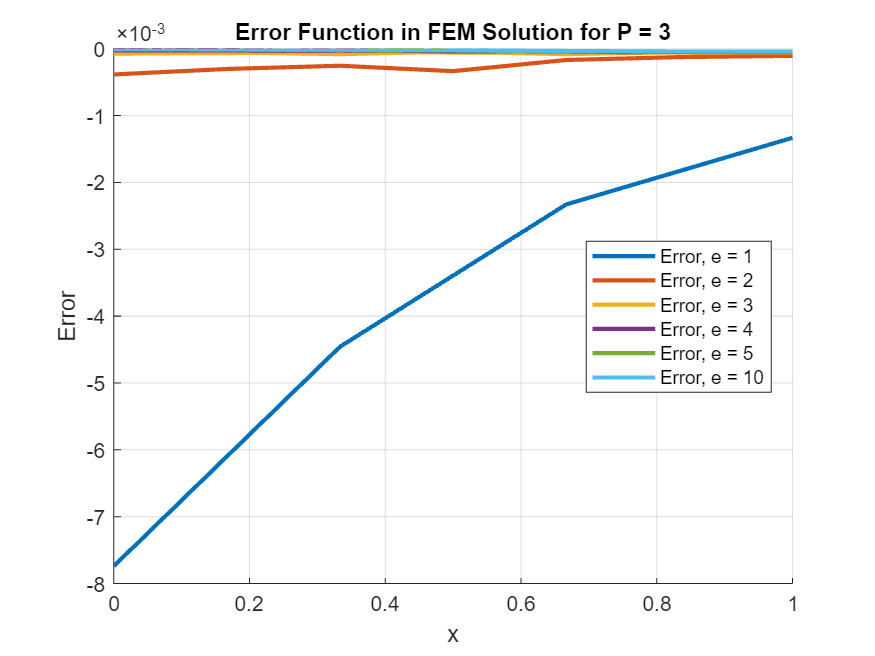


% Assume u_exact_equation is already defined and simplified
for p_idx = 1:length(P_values)
    P = P_values(p_idx);
    figure; % Create a new figure for each P
    hold on;
    for i = 1:length(elements)
        X_nodes = X_nodes_store{i, p_idx}; % Node locations for this element count and P
        u_nodes = u_nodes_store{i, p_idx}; % FEM solutions at these nodes

        % Calculate exact solution at nodes
        U_exact_at_nodes = double(subs(u_exact_equation, x, X_nodes));

        % Compute error at nodes
        error_at_nodes = U_exact_at_nodes - u_nodes;

        % Plot error
        plot(X_nodes, error_at_nodes,  'LineWidth', 2, ...
            'DisplayName', ['Error, e = ' num2str(elements(i))]);
    end
    
    xlabel('x');
    ylabel('Error');
    title(['Error Function in FEM Solution for P = ' num2str(P)]);
    legend('Location', 'best');
    grid on;
    hold off;
end


du_exact_equation = diff(u_exact_equation,x)

$$du\_exact\_equation = \frac{1591423\,\cos\left(\frac{1571\,x}{500}\right)}{5000000}$$

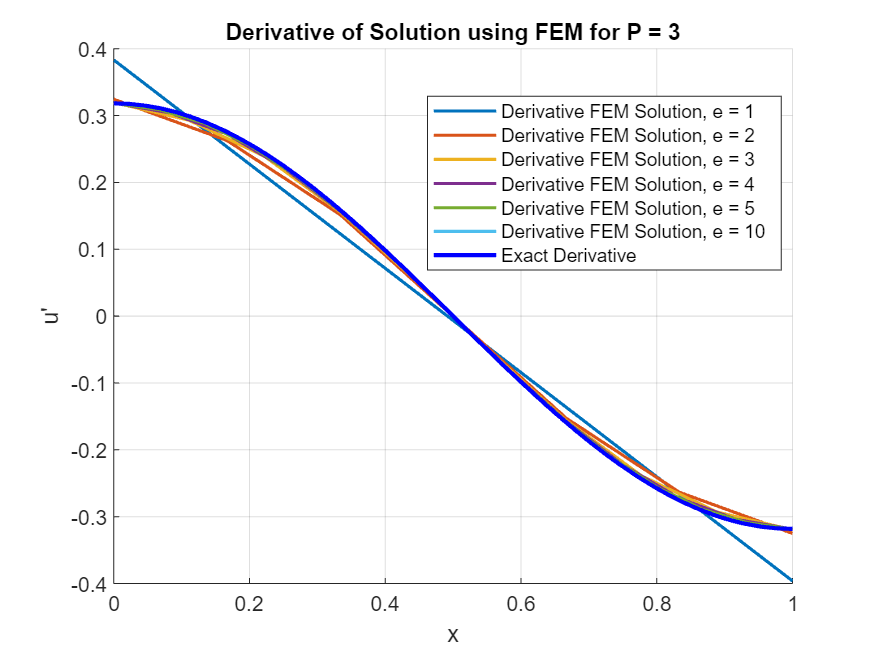


% Assume u_exact_equation and its setup are defined earlier
for p_idx = 1:length(P_values)
    P = P_values(p_idx);
    % Create a new figure for each P for derivatives
    figure;
    hold on;
    for i = 1:length(elements)
        X_nodes = X_nodes_store{i, p_idx};
        u_nodes = u_nodes_store{i, p_idx};
        h = X_nodes(2) - X_nodes(1); % Calculate the spatial step size

        % Calculate derivatives using the custom function
        du_dx = calculateGeneralDerivative(u_nodes, h, 1, 4, 4);

        % Plot derivative of FEM solution
        plot(X_nodes, du_dx, 'LineWidth', 1.5, ...
            'DisplayName', ['Derivative FEM Solution, e = ' num2str(elements(i))]);
    end
    
    % Plot the exact derivative solution
    fplot(du_exact_equation, [x0, xL], 'b', 'LineWidth', 2, ...
        'DisplayName', 'Exact Derivative');
    
    xlabel('x');
    ylabel("u'");
    title(['Derivative of Solution using FEM for P = ' num2str(P)]);
    legend('Location', 'best');
    grid on;
    hold off;
end